## **Abdullah Ahmed**

## **aa09303**

**Task 1)**

ftable = [1;2;3;4;5]*[80,110] % generate Table

ftable =     80   110
   160   220
   240   330
   320   440
   400   550


fs = 8000; xx = [ ]; % sample freq and output initialisation
keys = rem(3:12,10) + 1; % key presses = 4 5 6 7 8 9 10 1 2 3

dur=0.15; % 0.15s duration
t=0:1/fs:dur; % break 0.15s into 8000 samples

for ii = 1:length(keys)
    kk = keys(ii); % access key
    xx = [xx,zeros(1,400)]; % silence for 0.05s
    krow = ceil(kk/2) ; % map key to a row
    kcol = rem(kk-1,2) + 1; % map key to a column
    xx = [xx, cos(2*pi*ftable(krow,kcol)*t)]; % add the audio signal of the key to the output
end

soundsc(xx,fs); % play the sound

1) The program uses a frequency table (`ftable`) to map keys to specific frequencies. It iterates through a sequence of keys, selecting corresponding row and column values from `ftable` to generate cosine waves at those frequencies. Each tone is concatenated with a short silence, forming a long signal. Finally, the signal is played using `soundsc()`, creating a sequence of tones similar to DTMF signals.

2) It is a 5 x 2 matrix

**220 Hz, 240 Hz, 330 Hz, 320 Hz, 440 Hz, 400 Hz, 550 Hz, 80 Hz, 110 Hz, 160 Hz**.

3)

 0.15 + 400/8000 = 0.2s per audio tone.

since there are 10 audio tones **duration** = 0.2s * 10 = **2s**

**num samples** = 2 * 8000 = **16000**

**Task 2)**

result = dtmfdial('123A456B789C*0#D', 8000); 
sound(result); 

**Task 3)**

fb = 852;
L = 51;
fs = 8000;
B = maxbeta(L, fb, fs);
disp(B);

    0.0395



**Task 4)**

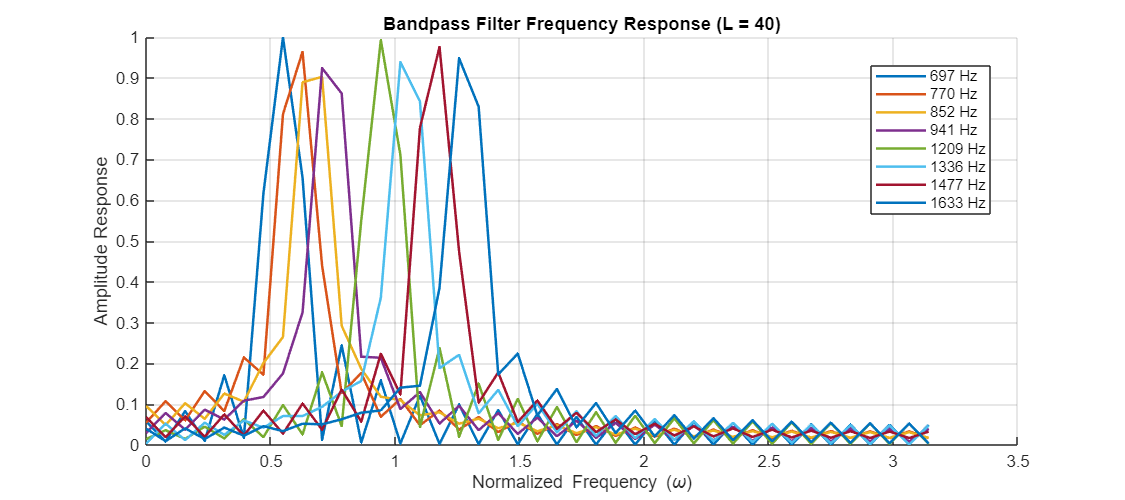

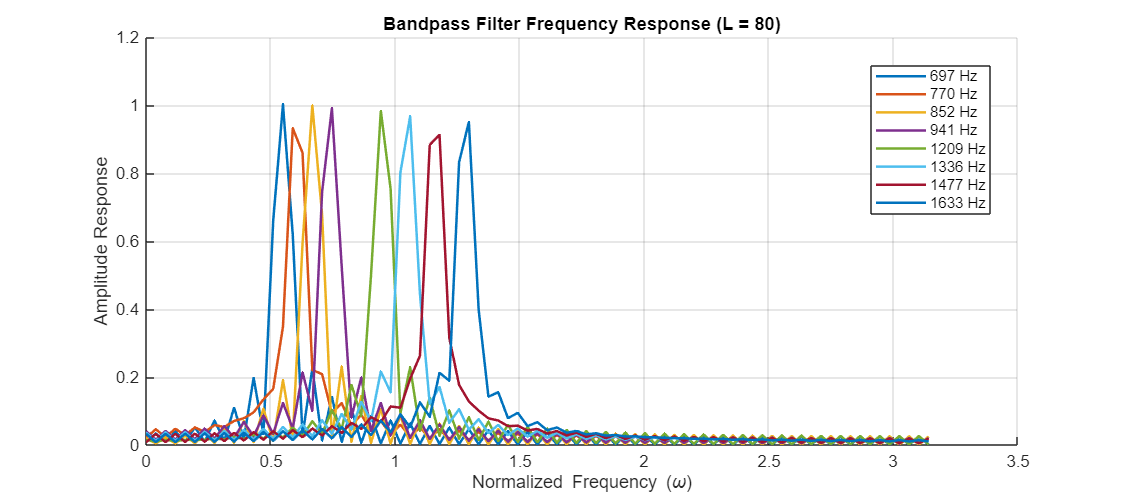

% Define DTMF tone frequencies
freqs = [697, 770, 852, 941, 1209, 1336, 1477, 1633]; 
Ls = [40, 80]; % Filter lengths to compare
fs = 8000; % Sampling frequency

% Loop through different values of L
for i = 1:length(Ls)
    L = Ls(i);
    hh = dtmfdesign(freqs, L, fs); % Generate bandpass filters
    
    % Create a new figure for each L
    figure('Position', [100, 100, 900, 400]);
    hold on;
    freqAxis = 0:pi/L:pi; % Frequency range for plotting

    % Plot the frequency responses of all filters
    for idx = 1:length(freqs)
        response = freqz(hh(:, idx), 1, freqAxis); 
        plot(freqAxis, abs(response), 'LineWidth', 1.5); % Thicker lines
    end

    hold off;
    xlabel('Normalized Frequency (\omega)');
    ylabel('Amplitude Response');
    title(['Bandpass Filter Frequency Response (L = ' num2str(L) ')']);
    legend(string(freqs) + " Hz", 'Location', 'Best');
    grid on;
end

**Comment:**

The selectivity of the bandpass filters determines how well they isolate their center frequency while rejecting others. With **L = 40**, the filters have broader passbands and less steep roll-offs, leading to poor selectivity and potential overlap with neighboring frequencies. For **L = 80**, the passbands become narrower and more selective, isolating the target frequency better.

Since the same **L** is used for all filters, the **697 Hz** filter is the most challenging. Lower frequencies require longer filters to achieve good resolution, so for a fixed **L**, the 697 Hz filter has the **widest bandwidth**, making it the least selective. Therefore, the 697 Hz filter drives the need for a longer filter length to meet the required specifications.

**Task 5**

function sc = dtmfscore(xx, hh)
    % Normalize the input signal
    xx = xx * (2 / max(abs(xx)));
    
    % Convolve input with filter
    yn = conv(xx, hh);
    
    % Check if maximum absolute value meets threshold
    if max(abs(yn)) >= 0.59
        sc = 1;
    else
        sc = 0;
    end
end

**Explaination:**

The scoring rule in `dtmfscore` relies on having predictable and consistent output when a DTMF tone is passed through a bandpass filter. For this to work, each filter must have a maximum frequency response magnitude (|H(e^jω)|) equal to 1 at its center frequency.

This is important because the DTMF tone is made up of two sinusoids, each with an amplitude of 1. After normalization, the combined tone can reach a peak of 2. If the filter passes its center frequency with a gain of exactly 1, then the output amplitude is known and consistent. This makes it possible to use a fixed threshold (like 0.59) to decide if the tone is present.

If the filter gain were not 1, the output amplitude would vary depending on the filter, leading to unreliable detection. A gain greater than 1 might cause false positives, and a gain less than 1 might cause missed detections. Therefore, normalizing the filter so that its frequency response has a maximum magnitude of 1 ensures accurate and consistent scoring for all tones.

**Task 6**

function keys = dtmfrun(xx, L, fs)
    %DTMFRUN    keys = dtmfrun(xx,L,fs)
    %    returns the list of key names found in xx.
    %   keys = array of characters, i.e., the decoded key names
    %     xx = DTMF waveform
    %      L = filter length
    %     fs = sampling freq

    % Define center frequencies (DTMF standard frequencies)
    row_freqs = [697, 770, 852, 941];
    col_freqs = [1209, 1336, 1477, 1633];
    center_freqs = [row_freqs, col_freqs];  % Total 8 frequencies

    % Create filter bank
    hh = dtmfdesign(center_freqs, L, fs);  % L x 8 matrix

    % Find tone bursts
    [nstart, nstop] = dtmfcut(xx, fs);

    % DTMF keypad
    dtmf_keys = [
        '1','2','3','A';
        '4','5','6','B';
        '7','8','9','C';
        '*','0','#','D'
    ];

    keys = [];  % Output keys
    for kk = 1:length(nstart)
        x_seg = xx(nstart(kk):nstop(kk));  % Extract tone segment

        score = zeros(1, 8);
        for ii = 1:8
            score(ii) = dtmfscore(x_seg, hh(:, ii));  % Score for each filter
        end

        row_index = find(score(1:4));  % Only row filters
        col_index = find(score(5:8));  % Only column filters

        if length(row_index) == 1 && length(col_index) == 1
            keys(end+1) = dtmf_keys(row_index, col_index);  % Map to keypad
        end
        % Else do nothing (skip unrecognized tones)
    end
end

**Task 7**

clc;
clear;
close all;
fs = 8000; %¡--use this sampling rate in all functions
tk = ['4', '0', '7', '*', '8', '9', '1', '3', '2', 'B', 'A', 'D', 'C'];
xx = dtmfdial( tk, fs );
soundsc(xx, fs);
L = 200;
char(dtmfrun(xx, L, fs))

ans = '407*89132BADC'

**Functions**

% TASK 2
function xx = dtmfdial(keyNames, fs)
    % Define the DTMF keypad layout
    dtmf.keys = [
        '1','2','3','A';
        '4','5','6','B';
        '7','8','9','C';
        '*','0','#','D'
    ];
    
    dtmf.colTones = [1209, 1336, 1477, 1633];
    dtmf.rowTones = [697; 770; 852; 941];

    dur = 0.20;
    t = 0:1/fs:dur;
    silenceLength = 400;
    numKeys = length(keyNames);
    toneLength = length(t);
    totalLength = numKeys * (toneLength + silenceLength);
   
    xx = zeros(1, totalLength);
    
    index = 1;
    for key = keyNames
        [ii, jj] = find(key == dtmf.keys);
        tone = cos(2 * pi * dtmf.rowTones(ii) * t) + cos(2 * pi * dtmf.colTones(jj) * t);
        xx(index:index+toneLength-1) = tone;
        index = index + toneLength + silenceLength;
    end
end

% TASK 3
function B = maxbeta(L, fb, fs)
    n = 0:L-1;
    h = cos(2 * pi * fb * n / fs);
    
    % frequency response
    H = abs(fft(h, 1024));
    maxH = max(H);

    B = 1 / maxH;
end

% TASK 4
function hh = dtmfdesign(fcent, L, fs)
    numFilters = length(fcent);
    hh = zeros(L, numFilters); % Initialize matrix
    n = 0:L-1; % Time index

    for k = 1:numFilters 
        fb = fcent(k); % Center frequency
        h = cos(2 * pi * fb * n / fs); % Impulse response
        beta = maxbeta(L, fb, fs);
        hh(:, k) = beta * h; % store
    end 
end

% TASK 5
function sc = dtmfscore(xx, hh)
    % Normalize the input signal
    xx = xx * (2 / max(abs(xx)));
    
    % Convolve input with filter
    yn = conv(xx, hh);
    
    % Check if maximum absolute value meets threshold
    if max(abs(yn)) >= 0.59
        sc = 1;
    else
        sc = 0;
    end
end

% TASK 6
function keys = dtmfrun(xx, L, fs)
    %DTMFRUN    keys = dtmfrun(xx,L,fs)
    %    returns the list of key names found in xx.
    %   keys = array of characters, i.e., the decoded key names
    %     xx = DTMF waveform
    %      L = filter length
    %     fs = sampling freq

    % Define center frequencies (DTMF standard frequencies)
    row_freqs = [697, 770, 852, 941];
    col_freqs = [1209, 1336, 1477, 1633];
    center_freqs = [row_freqs, col_freqs];  % Total 8 frequencies

    % Create filter bank
    hh = dtmfdesign(center_freqs, L, fs);  % L x 8 matrix

    % Find tone bursts
    [nstart, nstop] = dtmfcut(xx, fs);

    % DTMF keypad
    dtmf_keys = [
        '1','2','3','A';
        '4','5','6','B';
        '7','8','9','C';
        '*','0','#','D'
    ];

    keys = [];  % Output keys
    for kk = 1:length(nstart)
        x_seg = xx(nstart(kk):nstop(kk));  % Extract tone segment

        score = zeros(1, 8);
        for ii = 1:8
            score(ii) = dtmfscore(x_seg, hh(:, ii));  % Score for each filter
        end

        row_index = find(score(1:4));  % Only row filters
        col_index = find(score(5:8));  % Only column filters

        if length(row_index) == 1 && length(col_index) == 1
            keys(end+1) = dtmf_keys(row_index, col_index);  % Map to keypad
        end
        % Else do nothing (skip unrecognized tones)
    end
end
